# **Computational Assignment 1**

**EE4140 - Digital Communication Systems**

**Jayadev Joy (EE18B011) **

***Department of Electrical Engineering, IIT Madras***

*12 September 2022*

*I certify that this experiment submission is my own work and not obtained from any other source.*

## 1. Raised cosine pulse shaped transmission

### 1.1 Initializing the RC filter parameters

beta = 0;       % Excess bandwidth factor
J = 4;          % Oversampling factor
N = 32;         % Input signal bit length

### 1.2 Output sequence plots for various values of L

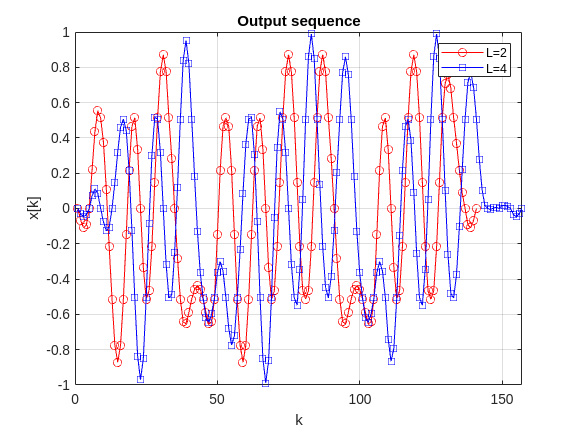

i_k = binornd(1,0.5,[1 N]);
i_k_bpsk = bpsk_mod(i_k, 1);

L = 2;          % Filter span in symbol durations (in one direction)
x1 = upfirdn(i_k_bpsk, rcosdesign(beta,2*L,J,"normal"), J);

L = 4;
x2 = upfirdn(i_k_bpsk, rcosdesign(beta,2*L,J,"normal"), J);

figure(1)
plot(x1,'-or')
hold on
plot(x2,'-sb')
grid on
title('Output sequence')
xlabel('k')
ylabel('x[k]')
legend('L=2','L=4')
hold off

### 1.2 Output sequence plots for various values of $\beta \;$

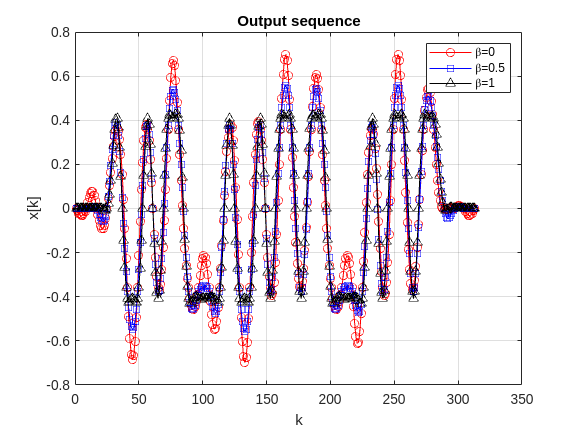

L = 4;
J = 8;

beta = 0;
x3 = upfirdn(i_k_bpsk, rcosdesign(beta,2*L,J,"normal"), J);

beta = 0.5;
x4 = upfirdn(i_k_bpsk, rcosdesign(beta,2*L,J,"normal"), J);

beta = 1;
x5 = upfirdn(i_k_bpsk, rcosdesign(beta,2*L,J,"normal"), J);

figure(2)
plot(x3,'-or')
hold on
plot(x4,'-sb')
hold on
plot(x5,'-^k')
grid on
title('Output sequence')
xlabel('k')
ylabel('x[k]')
legend('\beta=0','\beta=0.5','\beta=1')
hold off

### 1.3 Plotting the PSD using Periodogram (RC & rectangular pulse shape)

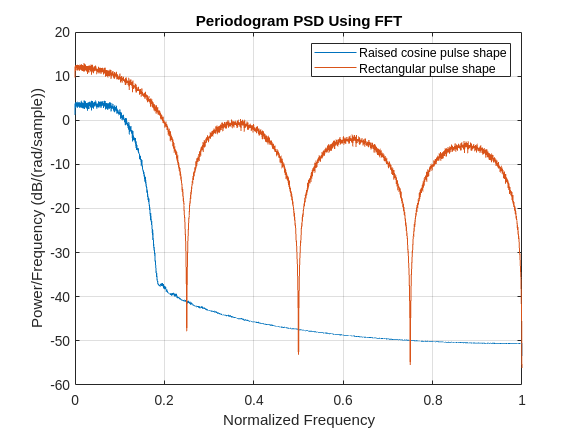

R = 100;
N = 1024;
L = 4;
beta = 0.5;
J = 8;

psdx_avg_1 = zeros([1 (N*J/2)+1]);
psdx_avg_2 = zeros([1 (N*J/2)+1]);

for i = 1:R
    i_k = binornd(1,0.5,[1 N]);
    i_k_bpsk = bpsk_mod(i_k, 1);
    x6 = upfirdn(i_k_bpsk, rcosdesign(beta,2*L,J,"normal"), J);
    x7 = upfirdn(i_k_bpsk, ones([1 J]), J);
    xdft1 = fft(x6,N*J);
    xdft2 = fft(x7,N*J);
    xdft1 = xdft1(1:(N*J)/2+1);
    xdft2 = xdft2(1:(N*J)/2+1);
    psdx1 = abs(xdft1).^2/(N*J);
    psdx2 = abs(xdft2).^2/(N*J);
    psdx1(2:end-1) = 2*psdx1(2:end-1);
    psdx2(2:end-1) = 2*psdx2(2:end-1);
    psdx_avg_1 = psdx_avg_1 + (psdx1/R);
    psdx_avg_2 = psdx_avg_2 + (psdx2/R);
end

figure(3)
plot(0:2/(N*J):1,10*log10(psdx_avg_1))
hold on
plot(0:2/(N*J):1,10*log10(psdx_avg_2))
grid on
title('Periodogram PSD Using FFT')
xlabel('Normalized Frequency')
ylabel('Power/Frequency (dB/(rad/sample))')
legend('Raised cosine pulse shape','Rectangular pulse shape')
hold off

## 2. Theoretical and experimental average SER & BER of various linear modulation schemes

### 2.1 Initializing the system parameters

len = 100000;
Eb = 1;
EbN0dB = 0:2:14;
EbN0 = 10.^(EbN0dB/10);
signal = binornd(1,0.5,[1 len]);

### 2.2 Computing the theoretical average SER (BPSK, QPSK & 16-QAM)

ser_bpsk_t = zeros([1 length(EbN0dB)]);
ser_qpsk_t = zeros([1 length(EbN0dB)]);
ser_16_qam_t = zeros([1 length(EbN0dB)]);

for i = 1:length(EbN0)
    q = qfunc(sqrt(Eb)/sqrt(Eb/(2*EbN0(i))));
    q_16_qam = qfunc(sqrt(Eb/2.5)/sqrt(Eb/(2*EbN0(i))));
    
    ser_bpsk_t(i) = q;
    ser_qpsk_t(i) = (2*q)-(q*q);
    ser_16_qam_t(i) = (3*q_16_qam)-(9*q_16_qam*q_16_qam/4);
end

### 2.3 Computing the approximate theoretical average SER (QPSK & 16-QAM)

ser_qpsk_1 = zeros([1 length(EbN0dB)]);
ser_qpsk_2 = zeros([1 length(EbN0dB)]);
ser_qpsk_3 = zeros([1 length(EbN0dB)]);
ser_16_qam_1 = zeros([1 length(EbN0dB)]);

for i = 1:length(EbN0)
    q = qfunc(sqrt(Eb)/sqrt(Eb/(2*EbN0(i))));
    q_16_qam = qfunc(sqrt(Eb/2.5)/sqrt(Eb/(2*EbN0(i))));

    ser_qpsk_1(i) = (2*q) + qfunc(sqrt(2*Eb)/sqrt(Eb/(2*EbN0(i))));
    ser_qpsk_2(i) = 2*q;
    ser_qpsk_3(i) = 2*exp(-EbN0(i));
    ser_16_qam_1(i) = 3*q_16_qam;
end

### 2.4 Computing the experimental average SER & BER (BPSK, QPSK & 16-QAM)

sig_bpsk = bpsk_mod(signal, Eb);
sig_qpsk = qpsk_mod(signal, Eb);
sig_16_qam = qam_16_mod(signal, Eb);

ser_bpsk = zeros([1 length(EbN0dB)]);
ser_qpsk = zeros([1 length(EbN0dB)]);
ser_16_qam = zeros([1 length(EbN0dB)]);

ber_bpsk = zeros([1 length(EbN0dB)]);
ber_qpsk = zeros([1 length(EbN0dB)]);
ber_16_qam = zeros([1 length(EbN0dB)]);

for i = 1:length(EbN0dB)
    sig_bpsk_awgn = awgn(sig_bpsk, Eb, EbN0(i));
    sig_qpsk_awgn = awgn(sig_qpsk, Eb, EbN0(i));
    sig_16_qam_awgn = awgn(sig_16_qam, Eb, EbN0(i));

    sig_bpsk_awgn_dem = bpsk_demod(sig_bpsk_awgn, Eb);
    sig_qpsk_awgn_dem = qpsk_demod(sig_qpsk_awgn, Eb);
    sig_16_qam_awgn_dem = qam_16_demod(sig_16_qam_awgn, Eb);

    ser_bpsk(i) = err(sig_bpsk, sig_bpsk_awgn_dem);
    ser_qpsk(i) = err(sig_qpsk, sig_qpsk_awgn_dem);
    ser_16_qam(i) = err(sig_16_qam, sig_16_qam_awgn_dem);

    ber_bpsk(i) = err(signal, bpsk_demod_bits(sig_bpsk_awgn));
    ber_qpsk(i) = err(signal, qpsk_demod_bits(sig_qpsk_awgn));
    ber_16_qam(i) = err(signal, qam_16_demod_bits(sig_16_qam_awgn, Eb));    
end

### 2.5 Required SER & BER plots (BPSK, QPSK & 16-QAM)

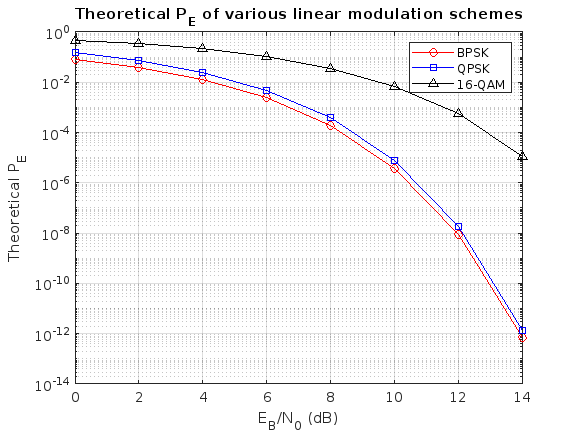

figure(4)
semilogy(EbN0dB,ser_bpsk_t,'-or')
hold on
semilogy(EbN0dB,ser_qpsk_t,'-sb')
hold on
semilogy(EbN0dB,ser_16_qam_t,'-^k')
grid on
title('Theoretical P_{E} of various linear modulation schemes')
xlabel('E_{B}/N_{0} (dB)')
ylabel('Theoretical P_{E}')
legend('BPSK','QPSK','16-QAM')
hold off

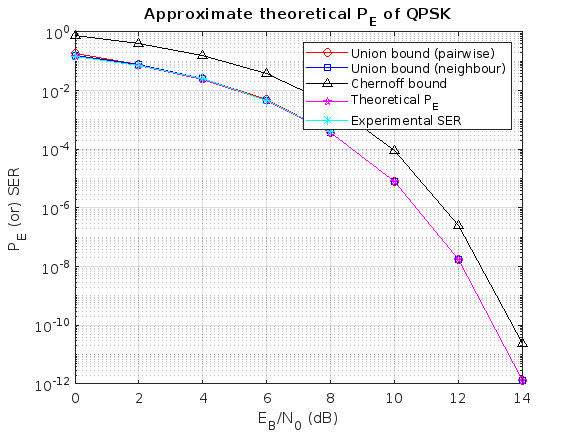

figure(5)
semilogy(EbN0dB,ser_qpsk_1,'-or')
hold on
semilogy(EbN0dB,ser_qpsk_2,'-sb')
hold on
semilogy(EbN0dB,ser_qpsk_3,'-^k')
hold on
semilogy(EbN0dB,ser_qpsk_t,'-pm')
hold on
semilogy(EbN0dB,ser_qpsk,'-*c')
grid on
title('Approximate theoretical P_{E} of QPSK')
xlabel('E_{B}/N_{0} (dB)')
ylabel('P_{E} (or) SER')
legend('Union bound (pairwise)','Union bound (neighbour)','Chernoff bound', 'Theoretical P_{E}', 'Experimental SER')
hold off

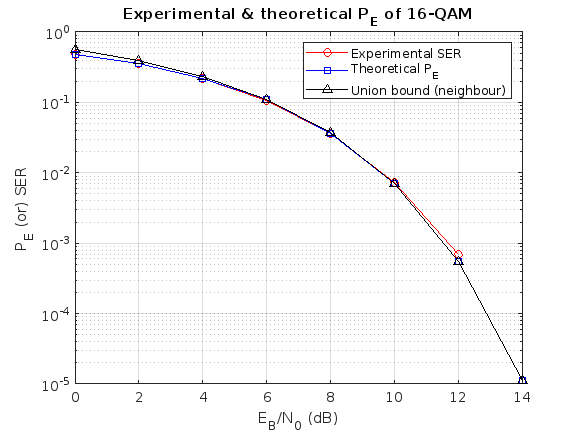

figure(6)
semilogy(EbN0dB,ser_16_qam,'-or')
hold on
semilogy(EbN0dB,ser_16_qam_t,'-sb')
hold on
semilogy(EbN0dB,ser_16_qam_1,'-^k')
grid on
title('Experimental & theoretical P_{E} of 16-QAM')
xlabel('E_{B}/N_{0} (dB)')
ylabel('P_{E} (or) SER')
legend('Experimental SER', 'Theoretical P_{E}', 'Union bound (neighbour)')
hold off

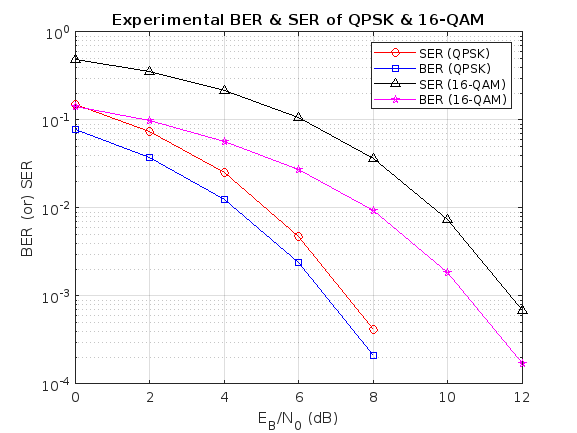

figure(7)
semilogy(EbN0dB,ser_qpsk,'-or')
hold on
semilogy(EbN0dB,ber_qpsk,'-sb')
hold on
semilogy(EbN0dB,ser_16_qam,'-^k')
hold on
semilogy(EbN0dB,ber_16_qam,'-pm')
grid on
title('Experimental BER & SER of QPSK & 16-QAM')
xlabel('E_{B}/N_{0} (dB)')
ylabel('BER (or) SER')
legend('SER (QPSK)','BER (QPSK)','SER (16-QAM)', 'BER (16-QAM)')
hold off

## 3. Different functions used in the simulations

function x = bpsk_mod(sig, eb)
    xi = zeros([1 length(sig)]);
    for i = 1:length(sig)
        if sig(i) == 0
            xi(i) = -sqrt(eb);
        else
            xi(i) = sqrt(eb);
        end
    end
    x = xi;
end

function x = bpsk_demod(sym, eb)
    xi = zeros([1 length(sym)]);
    for i = 1:length(sym)
        if sym(i) >= 0
            xi(i) = sqrt(eb);
        else
            xi(i) = -sqrt(eb);
        end
    end
    x = xi;
end

function x = bpsk_demod_bits(sym)
    xi = zeros([1 length(sym)]);
    for i = 1:length(sym)
        if sym(i) >= 0
            xi(i) = 1;
        else
            xi(i) = 0;
        end
    end
    x = xi;
end

function x = qpsk_mod(sig, eb)
    xi = zeros([1 (length(sig)/2)]);
    d = sqrt(eb);
    for i = 1:length(xi)
        if (sig(2*i-1) == 1) && (sig(2*i) == 1)
            xi(i) = complex(d,d);
        elseif (sig(2*i-1) == 1) && (sig(2*i) == 0)
            xi(i) = complex(d,-d);
        elseif (sig(2*i-1) == 0) && (sig(2*i) == 1)
            xi(i) = complex(-d,d);
        elseif (sig(2*i-1) == 0) && (sig(2*i) == 0)
            xi(i) = complex(-d,-d);
        end
    end
    x = xi;
end

function x = qpsk_demod(sym, eb)
    xi = zeros([1 length(sym)]);
    d = sqrt(eb);    
    for i = 1:length(sym)
        if (real(sym(i)) >= 0) && (imag(sym(i)) >= 0)
            xi(i) = complex(d,d);
        elseif (real(sym(i)) >= 0) && (imag(sym(i)) < 0)
            xi(i) = complex(d,-d);
        elseif (real(sym(i)) < 0) && (imag(sym(i)) >= 0)
            xi(i) = complex(-d,d);
        elseif (real(sym(i)) < 0) && (imag(sym(i)) < 0)
            xi(i) = complex(-d,-d);
        end
    end
    x = xi;
end

function x = qpsk_demod_bits(sym)
    xi = zeros([1 (length(sym)*2)]);
    for i = 1:length(sym)
        if (real(sym(i)) >= 0) && (imag(sym(i)) >= 0)
            xi(2*i-1) = 1;
            xi(2*i) = 1;
        elseif (real(sym(i)) >= 0) && (imag(sym(i)) < 0)
            xi(2*i-1) = 1;
            xi(2*i) = 0;
        elseif (real(sym(i)) < 0) && (imag(sym(i)) >= 0)
            xi(2*i-1) = 0;
            xi(2*i) = 1;
        elseif (real(sym(i)) < 0) && (imag(sym(i)) < 0)
            xi(2*i-1) = 0;
            xi(2*i) = 0;
        end
    end
    x = xi;
end

function x = qam_16_mod(sig, eb)
    xi = zeros([1 (length(sig)/4)]);
    d = sqrt(eb/2.5);
    for i = 1:length(xi)
        if (sig(4*i-3) == 1) && (sig(4*i-2) == 0) && (sig(4*i-1) == 0) && (sig(4*i) == 0)
            xi(i) = complex(3*d,3*d);
        elseif (sig(4*i-3) == 1) && (sig(4*i-2) == 1) && (sig(4*i-1) == 0) && (sig(4*i) == 0)
            xi(i) = complex(d,3*d);
        elseif (sig(4*i-3) == 1) && (sig(4*i-2) == 1) && (sig(4*i-1) == 0) && (sig(4*i) == 1)
            xi(i) = complex(d,d);
        elseif (sig(4*i-3) == 1) && (sig(4*i-2) == 0) && (sig(4*i-1) == 0) && (sig(4*i) == 1)
            xi(i) = complex(3*d,d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 0) && (sig(4*i-1) == 0) && (sig(4*i) == 0)
            xi(i) = complex(-3*d,3*d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 1) && (sig(4*i-1) == 0) && (sig(4*i) == 0)
            xi(i) = complex(-d,3*d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 1) && (sig(4*i-1) == 0) && (sig(4*i) == 1)
            xi(i) = complex(-d,d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 0) && (sig(4*i-1) == 0) && (sig(4*i) == 1)
            xi(i) = complex(-3*d,d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 0) && (sig(4*i-1) == 1) && (sig(4*i) == 0)
            xi(i) = complex(-3*d,-3*d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 1) && (sig(4*i-1) == 1) && (sig(4*i) == 0)
            xi(i) = complex(-d,-3*d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 1) && (sig(4*i-1) == 1) && (sig(4*i) == 1)
            xi(i) = complex(-d,-d);
        elseif (sig(4*i-3) == 0) && (sig(4*i-2) == 0) && (sig(4*i-1) == 1) && (sig(4*i) == 1)
            xi(i) = complex(-3*d,-d);
        elseif (sig(4*i-3) == 1) && (sig(4*i-2) == 0) && (sig(4*i-1) == 1) && (sig(4*i) == 0)
            xi(i) = complex(3*d,-3*d);
        elseif (sig(4*i-3) == 1) && (sig(4*i-2) == 1) && (sig(4*i-1) == 1) && (sig(4*i) == 0)
            xi(i) = complex(d,-3*d);
        elseif (sig(4*i-3) == 1) && (sig(4*i-2) == 1) && (sig(4*i-1) == 1) && (sig(4*i) == 1)
            xi(i) = complex(d,-d);
        elseif (sig(4*i-3) == 1) && (sig(4*i-2) == 0) && (sig(4*i-1) == 1) && (sig(4*i) == 1)
            xi(i) = complex(3*d,-d);            
        end
    end
    x = xi;
end

function x = qam_16_demod(sym, eb)
    xi = zeros([1 length(sym)]);
    d = sqrt(eb/2.5);
    for i = 1:length(sym)
        if (real(sym(i)) >= 2*d) && (imag(sym(i)) >= 2*d)
            xi(i) = complex(3*d,3*d);
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) >= 2*d)
            xi(i) = complex(d,3*d);   
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(i) = complex(d,d);               
        elseif (real(sym(i)) >= 2*d) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(i) = complex(3*d,d);   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) >= 2*d)
            xi(i) = complex(-3*d,3*d);   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) >= 2*d)
            xi(i) = complex(-d,3*d);   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(i) = complex(-d,d);   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(i) = complex(-3*d,d);   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) <= -2*d)
            xi(i) = complex(-3*d,-3*d);   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) <= -2*d)
            xi(i) = complex(-d,-3*d);   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(i) = complex(-d,-d);   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(i) = complex(-3*d,-d);   
        elseif (real(sym(i)) >= 2*d) && (imag(sym(i)) <= -2*d)
            xi(i) = complex(3*d,-3*d);   
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) <= -2*d)
            xi(i) = complex(d,-3*d);   
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(i) = complex(d,-d);   
        elseif (real(sym(i)) >= 2*d) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(i) = complex(3*d,-d);               
        end
    end
    x = xi;
end

function x = qam_16_demod_bits(sym, eb)
    xi = zeros([1 (length(sym)*4)]);
    d = sqrt(eb/2.5);
    for i = 1:length(sym)
        if (real(sym(i)) >= 2*d) && (imag(sym(i)) >= 2*d)
            xi(4*i-3) = 1;
            xi(4*i-2) = 0;
            xi(4*i-1) = 0;
            xi(4*i) = 0;
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) >= 2*d)
            xi(4*i-3) = 1;
            xi(4*i-2) = 1;
            xi(4*i-1) = 0;
            xi(4*i) = 0;   
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(4*i-3) = 1;
            xi(4*i-2) = 1;
            xi(4*i-1) = 0;
            xi(4*i) = 1;               
        elseif (real(sym(i)) >= 2*d) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(4*i-3) = 1;
            xi(4*i-2) = 0;
            xi(4*i-1) = 0;
            xi(4*i) = 1;   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) >= 2*d)
            xi(4*i-3) = 0;
            xi(4*i-2) = 0;
            xi(4*i-1) = 0;
            xi(4*i) = 0;   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) >= 2*d)
            xi(4*i-3) = 0;
            xi(4*i-2) = 1;
            xi(4*i-1) = 0;
            xi(4*i) = 0;   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(4*i-3) = 0;
            xi(4*i-2) = 1;
            xi(4*i-1) = 0;
            xi(4*i) = 1;   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) >= 0) && (imag(sym(i)) <= 2*d)
            xi(4*i-3) = 0;
            xi(4*i-2) = 0;
            xi(4*i-1) = 0;
            xi(4*i) = 1;   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) <= -2*d)
            xi(4*i-3) = 0;
            xi(4*i-2) = 0;
            xi(4*i-1) = 1;
            xi(4*i) = 0;   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) <= -2*d)
            xi(4*i-3) = 0;
            xi(4*i-2) = 1;
            xi(4*i-1) = 1;
            xi(4*i) = 0;   
        elseif (real(sym(i)) >= -2*d) && (real(sym(i)) <= 0) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(4*i-3) = 0;
            xi(4*i-2) = 1;
            xi(4*i-1) = 1;
            xi(4*i) = 1;   
        elseif (real(sym(i)) <= -2*d) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(4*i-3) = 0;
            xi(4*i-2) = 0;
            xi(4*i-1) = 1;
            xi(4*i) = 1;   
        elseif (real(sym(i)) >= 2*d) && (imag(sym(i)) <= -2*d)
            xi(4*i-3) = 1;
            xi(4*i-2) = 0;
            xi(4*i-1) = 1;
            xi(4*i) = 0;   
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) <= -2*d)
            xi(4*i-3) = 1;
            xi(4*i-2) = 1;
            xi(4*i-1) = 1;
            xi(4*i) = 0;   
        elseif (real(sym(i)) >= 0) && (real(sym(i)) <= 2*d) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(4*i-3) = 1;
            xi(4*i-2) = 1;
            xi(4*i-1) = 1;
            xi(4*i) = 1;   
        elseif (real(sym(i)) >= 2*d) && (imag(sym(i)) >= -2*d) && (imag(sym(i)) <= 0)
            xi(4*i-3) = 1;
            xi(4*i-2) = 0;
            xi(4*i-1) = 1;
            xi(4*i) = 1;               
        end
    end
    x = xi;
end

function x = awgn(sig, eb, ebn0)
    if all(imag(sig) == 0)
        x = sig + normrnd(0,sqrt(eb/(2*ebn0)),[1 length(sig)]);
    else
        x = sig + complex(normrnd(0,sqrt(eb/(2*ebn0)),[1 length(sig)]),normrnd(0,sqrt(eb/(2*ebn0)),[1 length(sig)]));
    end
end

function x = err(sym_org, sym_demod)
    x = sum(sym_org ~= sym_demod)/length(sym_org);
end